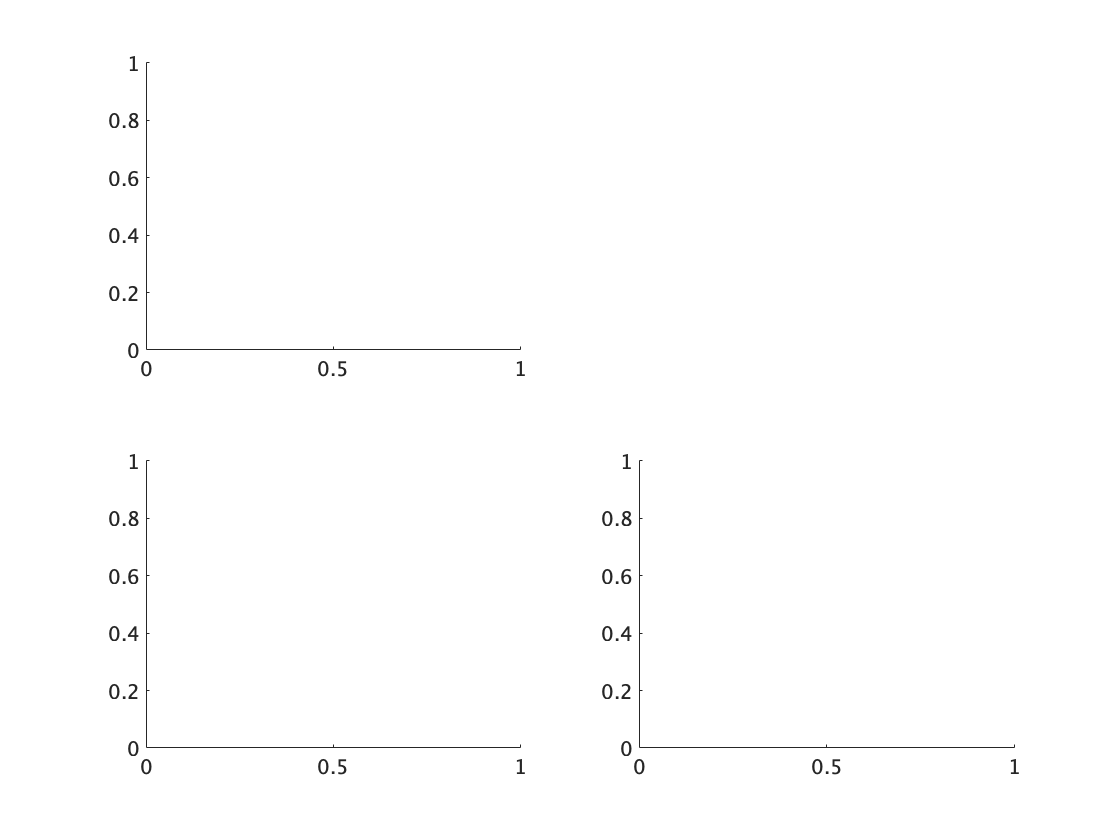

clear all; clf; clc;
AdvanpixMCT='AdvanpixMCT-4.8.3.14460/';
if ismac
    addpath("/Users/hanada/OneDrive/Packages/qtmaplab/");
    addpath(sprintf("/Users/hanada/Applications/%s",AdvanpixMCT));
elseif isunix
    [~, name] = system('hostname');
    if strcmp(strtrim(name), 'bohigas')
        addpath("/home/hanada/OneDrive/Packages/qtmaplab/");
        addpath(sprintf("/home/hanada/Applications/%s",AdvanpixMCT));        
    else
        addpath("/nfs/qtmaplab/");
        addpath("/nfs/AdvanpixMCT-4.8.3.14440/");
    end
end



domain = mp('[-pi pi;-pi pi]');
dim = 50;
basis = 'p';
sysinfo = SystemInfo(dim, domain);
state = FundamentalState(sysinfo, basis);

%p = uipanel('Position',[0 0 1 1]);
%t = tiledlayout(p,2,1);

fig = figure(1);
ax1 = subplot(2,2,1);
ax2 = subplot(2,2,4);
ax0 = subplot(2,2,3);
hold(ax1, 'on')
hold(ax2, 'on')
hold(ax0, 'on')



%qpc = [(rand(1) - 1/2) + qc, (rand(1) -1/2) + pc];
qpc = [mp('1') 2.1];
qpc = [2.1 mp('1')];
%class(qpc(1))
%qpc = [mp('1') mp('2')];
qpc = [1/3 2];
%qpc = [mp('1') mp('1')]
cs = state.coherent(qpc(1), qpc(2), 'verbose', true);

return 
plot(ax1, [qpc(1), qpc(1)], [-40, 1], '--k');
plot(ax2, [-40, 1], [qpc(2), qpc(2)], '--k');
%plot(ax0, domain(1,:), [qpc(1), qpc(1)], '--k');
%plot(ax0, [qpc(1), qpc1(1)], [domain(2,:)], '--k');

qvec = cs.qrep();

plot(ax1, qvec.x, log10(abs2(qvec)), 'ok')

pvec = cs.prep();
plot(ax2, log10(abs2(pvec)), pvec.x, 'ok')

qvec2 = pvec.p2q();
plot(ax1, qvec2.x, log10(abs2(qvec2)), '-r','LineWidth', 2)

pvec2 = qvec.q2p();
plot(ax2, log10(abs2(pvec2)), pvec2.x, '-r','LineWidth', 2)

[x,y,z] = cs.hsmrep();
contour(ax0, x, y, z, 20);
scatter(ax0, [qpc(1)], [qpc(2)], 50, 'filled',"ok")


xlim(ax1, double(domain(1,:)))
xlim(ax2, [-40 1])
xlim(ax0, double(domain(1,:)))
            
ylim(ax1, [-40 1])
ylim(ax2, double(domain(2,:)))
ylim(ax0, double(domain(2,:)))

xlabel(ax1, 'q')
ylabel(ax2, 'p')
xlabel(ax0, 'q')

ylabel(ax1, '|psi(q)|^2')
xlabel(ax2, '|psi(p)|^2')
ylabel(ax0, 'p')

%legend(ax1, 'qc','qrep()','qrep().q2p().p2q()','Location','southeast')
%legend(ax2, 'pc','prep()','prep().p2q().q2p()','Location','southeast')

legend(ax1, 'qc','qrep()','qrep().q2p().p2q()','Position',[0.52 0.8 0.1 0.1])
legend(ax2, 'pc','prep()','prep().p2q().q2p()','Position',[0.8 0.52 0.1 0.1])
legend(ax0, sprintf("qc=%.3f pc=%.3f", qpc(1), qpc(2)) )

hold(ax1, 'off')
hold(ax2, 'off')
hold(ax0, 'off')
%close(fig)